# [Solution] iTEBD: Ground state search

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the function for Vidal's original iTEBD

Check out the funciton `iTEBD_GS_Vidal.m` under the `DMRG` sub-directory. Compare with your implementation of `iTEBD_GS_Vidal_Ex.m`!

## Solution to Exercise (b): Check the energy convergence

In the demonstration, we use the following choice of parameters:

clear

% iTEBD parameters
Nkeep = 30;
tau_ini = 1; % initial imaginary time step size
tau_fin = 1e-6; % final imaginary time step size
Nstep = 2e3;

In this solution, I will see how iTEBD's performance changes with chaging (i) `tau_fin`, (ii) `Nstep`, or (iii) `Nkeep`. We use the same random MPS as the initial state, for fair comparison.

% Local operators
[S,I] = getLocalSpace('Spin',1);
% Heisenberg interaction as two-site gate S*S'
H = contract(S,3,3,permute(conj(S),[2 1 3]),3,3);

% Initialize with random Lambda and Gamma
Lambda_init = cell(1,2);
Gamma_init = cell(1,2);
for itn = (1:numel(Lambda_init))
    Lambda_init{itn} = rand(Nkeep,1);
    Gamma_init{itn} = rand(Nkeep,Nkeep,size(I,2));
end

% "numerically exact" value by White & Huse
Eexact = -1.401484039;

First, let's see the dependence of `tau_fin`.

tau_fins = 10.^(-4:-1:-8);
Eiters = cell(size(tau_fins));

for itt = (1:numel(Eiters))
    taus = tau_ini*((tau_fins(itt)/tau_ini).^linspace(0,1,Nstep));
    % iTEBD ground state search
    [~,~,Eiters{itt}] = iTEBD_GS_Vidal(Lambda_init,Gamma_init,H,Nkeep,taus);
end

22-10-02 12:17:20 | iTEBD ground state search: Bond dim. Nkeep = 30, # of imag. time steps = 2000
22-10-02 12:17:23 | #500/2000, E = -1.3935978
22-10-02 12:17:26 | #1000/2000, E = -1.4008203
22-10-02 12:17:28 | #1500/2000, E = -1.4014181
22-10-02 12:17:31 | #2000/2000, E = -1.4014766
Elapsed time: 11.45s, CPU time: 117.7s, Avg # of cores: 10.28
22-10-02 12:17:31 | Memory usage : 2.58GiB
22-10-02 12:17:31 | iTEBD ground state search: Bond dim. Nkeep = 30, # of imag. time steps = 2000
22-10-02 12:17:34 | #500/2000, E = -1.3973875
22-10-02 12:17:37 | #1000/2000, E = -1.4012757
22-10-02 12:17:40 | #1500/2000, E = -1.4014713
22-10-02 12:17:42 | #2000/2000, E = -1.4014822
Elapsed time: 11.14s, CPU time: 113.2s, Avg # of cores: 10.16
22-10-02 12:17:42 | Memory usage : 2.59GiB
22-10-02 12:17:42 | iTEBD ground state search: Bond dim. Nkeep = 30, # of imag. time steps = 2000
22-10-02 12:17:45 | #500/2000, E = -1.3992815
22-10-02 12:17:48 | #1000/2000, E = -1.4014172
22-10-02 12:17:50 | #1500/200

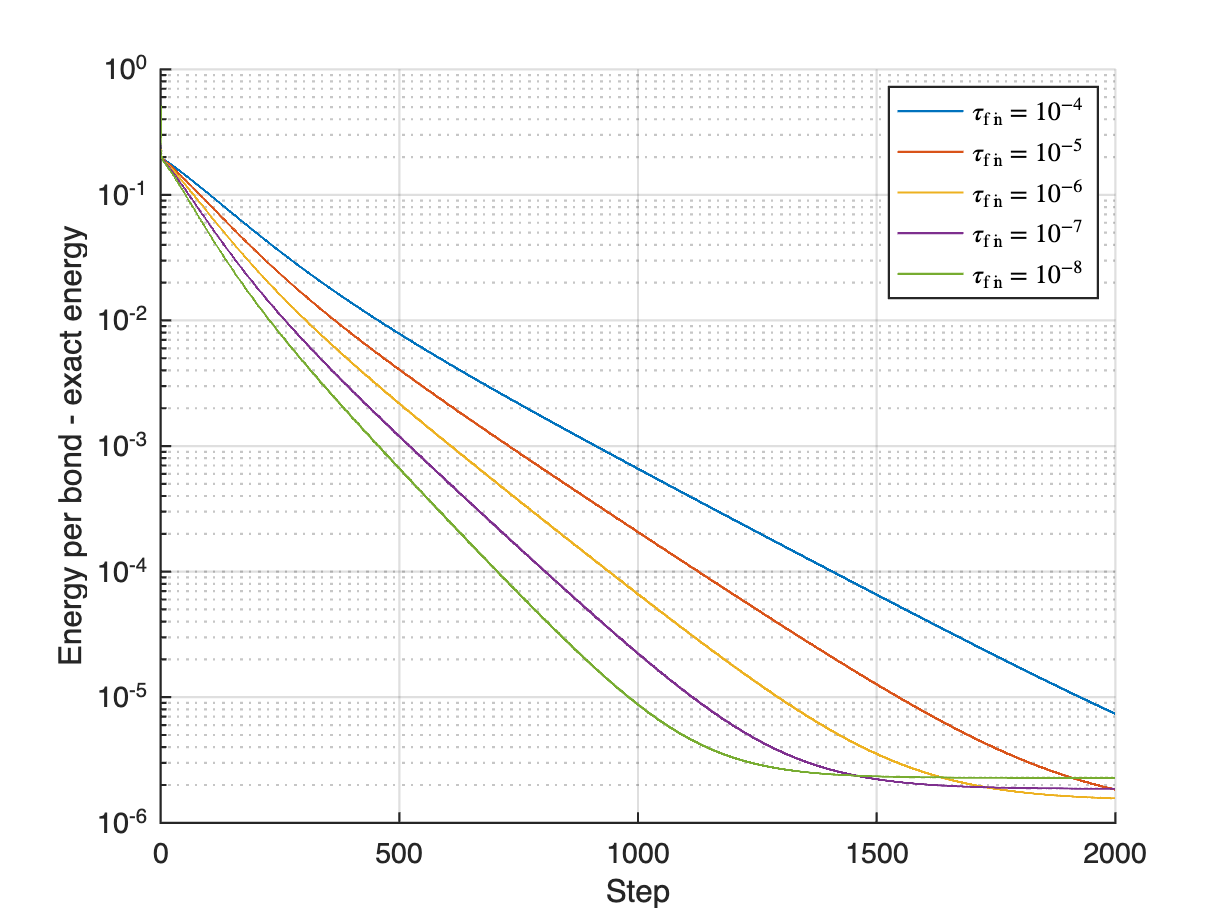

figure;
legs = cell(size(Eiters));
hold on;
for itt = (1:numel(Eiters))
    Eiter2 = reshape(permute(Eiters{itt},[2 1 3]), ...
        [size(Eiters{itt},2)*size(Eiters{itt},1) size(Eiters{itt},3)]);
    plot((1:size(Eiter2,1)).'/2,mean(Eiter2,2)-Eexact,'LineWidth',1);
    legs{itt} = ['$\tau_\mathrm{fin} = 10^{', ...
        sprintf('%i',log10(tau_fins(itt))),'}$'];
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Energy per bond - exact energy');
legend(legs{:},'Interpreter','latex');
grid on;

We find that for the largest `tau_fin`'s ($10^{-4}$ and $10^{-5}$) the energy has not fully converged. It is because larger step sizes in the last iterations lead to larger Trotterization error. For smaller `tau_fin`'s ($10^{-7}$ and $10^{-8}$) , the energy approaches faster, but the final value is larger than that for $10^{-6}$. It is because the total imaginary time interval is smaller than that for $10^{-6}$:

disp(sum(tau_ini*((tau_fins(3)/tau_ini).^linspace(0,1,Nstep)))); % 1e-6

  145.1929



disp(sum(tau_ini*((tau_fins(5)/tau_ini).^linspace(0,1,Nstep)))); % 1e-8

  109.0201



How about the dependence of `Nstep`?

Nsteps = (1e3:500:3e3);
Eiters = cell(size(Nsteps));

for itt = (1:numel(Eiters))
    taus = tau_ini*((tau_fin/tau_ini).^linspace(0,1,Nsteps(itt)));
    % iTEBD ground state search
    [~,~,Eiters{itt}] = iTEBD_GS_Vidal(Lambda_init,Gamma_init,H,Nkeep,taus);
end

22-10-02 12:18:16 | iTEBD ground state search: Bond dim. Nkeep = 30, # of imag. time steps = 1000
22-10-02 12:18:19 | #500/1000, E = -1.4014133
22-10-02 12:18:22 | #1000/1000, E = -1.4014795
Elapsed time: 6.371s, CPU time: 63.37s, Avg # of cores: 9.946
22-10-02 12:18:22 | Memory usage : 2.61GiB
22-10-02 12:18:22 | iTEBD ground state search: Bond dim. Nkeep = 30, # of imag. time steps = 1500
22-10-02 12:18:25 | #500/1500, E = -1.4008122
22-10-02 12:18:28 | #1000/1500, E = -1.4014752
22-10-02 12:18:31 | #1500/1500, E = -1.4014817
Elapsed time: 8.948s, CPU time: 91.27s, Avg # of cores: 10.2
22-10-02 12:18:31 | Memory usage : 2.61GiB
22-10-02 12:18:31 | iTEBD ground state search: Bond dim. Nkeep = 30, # of imag. time steps = 2000
22-10-02 12:18:34 | #500/2000, E = -1.3992815
22-10-02 12:18:37 | #1000/2000, E = -1.4014172
22-10-02 12:18:40 | #1500/2000, E = -1.4014805
22-10-02 12:18:42 | #2000/2000, E = -1.4014825
Elapsed time: 11.27s, CPU time: 116.1s, Avg # of cores: 10.31
22-10-02 12:18:

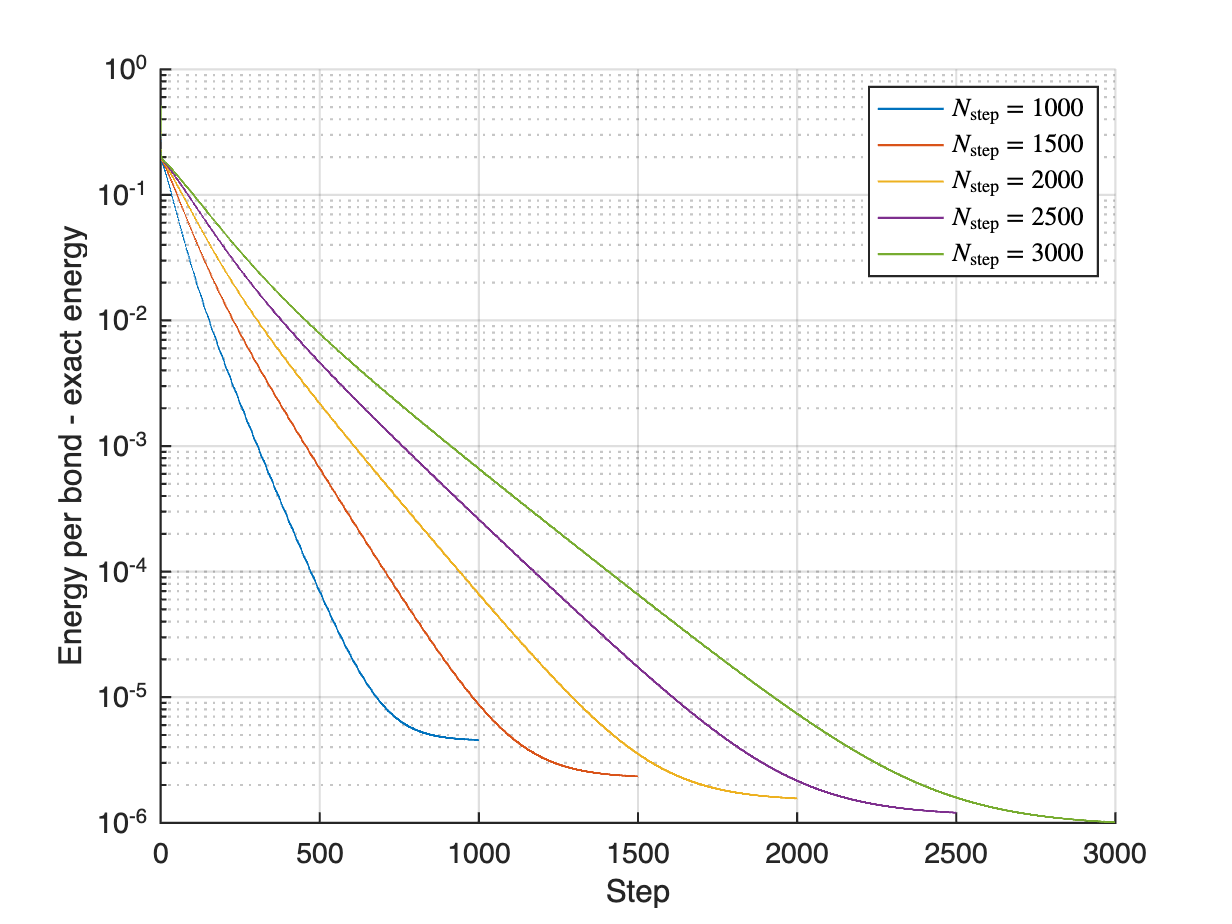

figure;
legs = cell(size(Eiters));
hold on;
for itt = (1:numel(Eiters))
    Eiter2 = reshape(permute(Eiters{itt},[2 1 3]), ...
        [size(Eiters{itt},2)*size(Eiters{itt},1) size(Eiters{itt},3)]);
    plot((1:size(Eiter2,1)).'/2,mean(Eiter2,2)-Eexact,'LineWidth',1);
    legs{itt} = ['$N_\mathrm{step} = ',sprintf('%i',Nsteps(itt)),'$'];
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Energy per bond - exact energy');
legend(legs{:},'Interpreter','latex');
grid on;

For smaller `Nstep`'s, the energy approaches faster, but the final value is larger than that for the largest `Nstep` (= 3000). It is because the total imaginary time interval is smaller.

As the last part of this analysis, we change `Nkeep`.

Nkeeps = (10:10:50);
Eiters = cell(size(Nkeeps));
taus = tau_ini*((tau_fin/tau_ini).^linspace(0,1,Nstep));

for itt = (1:numel(Eiters))
    % iTEBD ground state search
    [Lambda,Gamma,Eiters{itt}] = iTEBD_GS_Vidal(Lambda_init,Gamma_init,H,Nkeeps(itt),taus);
end

22-10-02 12:21:02 | iTEBD ground state search: Bond dim. Nkeep = 10, # of imag. time steps = 2000
22-10-02 12:21:03 | #500/2000, E = -1.3990145
22-10-02 12:21:04 | #1000/2000, E = -1.4011613
22-10-02 12:21:05 | #1500/2000, E = -1.401225
22-10-02 12:21:06 | #2000/2000, E = -1.401227
Elapsed time: 4.371s, CPU time: 5.8s, Avg # of cores: 1.327
22-10-02 12:21:06 | Memory usage : 2.78GiB
22-10-02 12:21:06 | iTEBD ground state search: Bond dim. Nkeep = 20, # of imag. time steps = 2000
22-10-02 12:21:08 | #500/2000, E = -1.3992544
22-10-02 12:21:10 | #1000/2000, E = -1.4013925
22-10-02 12:21:11 | #1500/2000, E = -1.4014559
22-10-02 12:21:13 | #2000/2000, E = -1.4014579
Elapsed time: 6.523s, CPU time: 52.98s, Avg # of cores: 8.123
22-10-02 12:21:13 | Memory usage : 2.79GiB
22-10-02 12:21:13 | iTEBD ground state search: Bond dim. Nkeep = 30, # of imag. time steps = 2000
22-10-02 12:21:16 | #500/2000, E = -1.3992815
22-10-02 12:21:18 | #1000/2000, E = -1.4014172
22-10-02 12:21:21 | #1500/2000, E

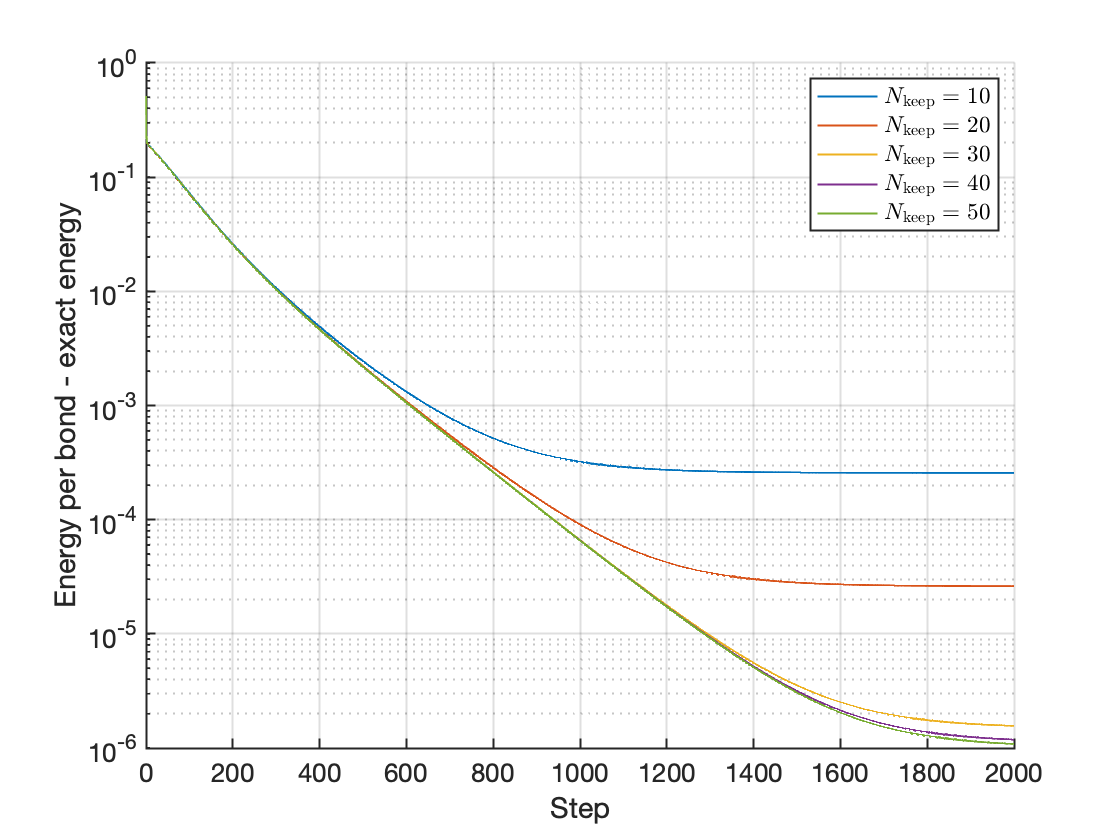

figure;
legs = cell(size(Eiters));
hold on;
for itt = (1:numel(Eiters))
    Eiter2 = reshape(permute(Eiters{itt},[2 1 3]), ...
        [size(Eiters{itt},2)*size(Eiters{itt},1) size(Eiters{itt},3)]);
    plot((1:size(Eiter2,1)).'/2,mean(Eiter2,2)-Eexact,'LineWidth',1);
    legs{itt} = ['$N_\mathrm{keep} = ',sprintf('%i',Nkeeps(itt)),'$'];
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Energy per bond - exact energy');
legend(legs{:},'Interpreter','latex');
grid on;

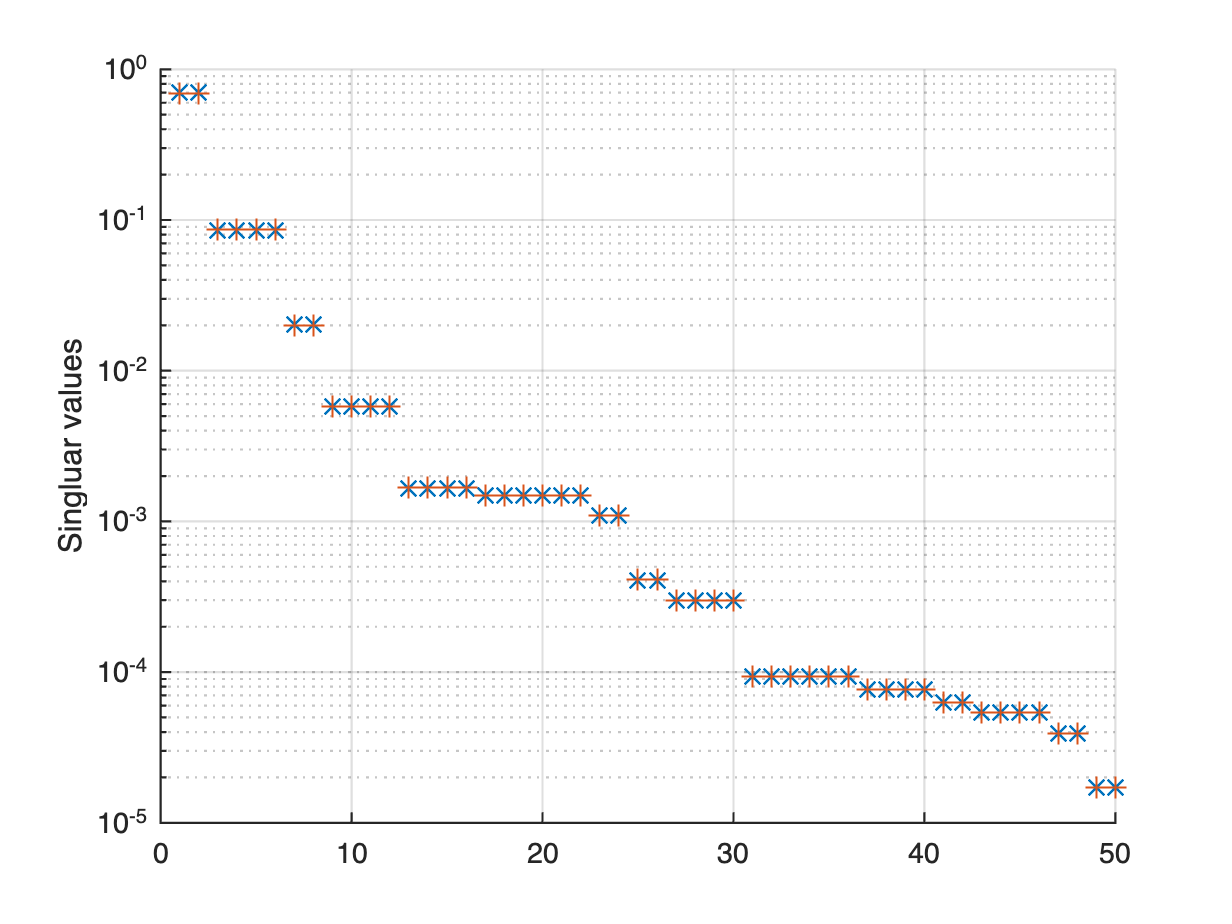

figure;
hold on;
plot((1:numel(Lambda{1})).',Lambda{1},'x','LineWidth',1,'MarkerSize',10);
plot((1:numel(Lambda{2})).',Lambda{2},'+','LineWidth',1,'MarkerSize',10);
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
ylabel('Singluar values');
grid on;

We find that the energy gets lower as `Nkeep` increases. The differences in the final energy values are due to the contibution from small singular values and the corresponding singular vectors (that would be discarded if `Nkeep` is smaller).